# Introducción: Tipos de datos en MATLAB

En MATLAB existen distintos tipos de datos que se utilizan en función de la situación y de la información. Generalmente se trabajará con matrices numéricas y arreglos de texto (caracter o cadena). No obstante, el conocimiento y uso del resto de tipos de datos (datos lógicos, tablas, etc.) puede facilitar considerablemente el trabajo dentro de este lenguaje de programación.

**Figura 1.** Tipos de datos en MATLAB.

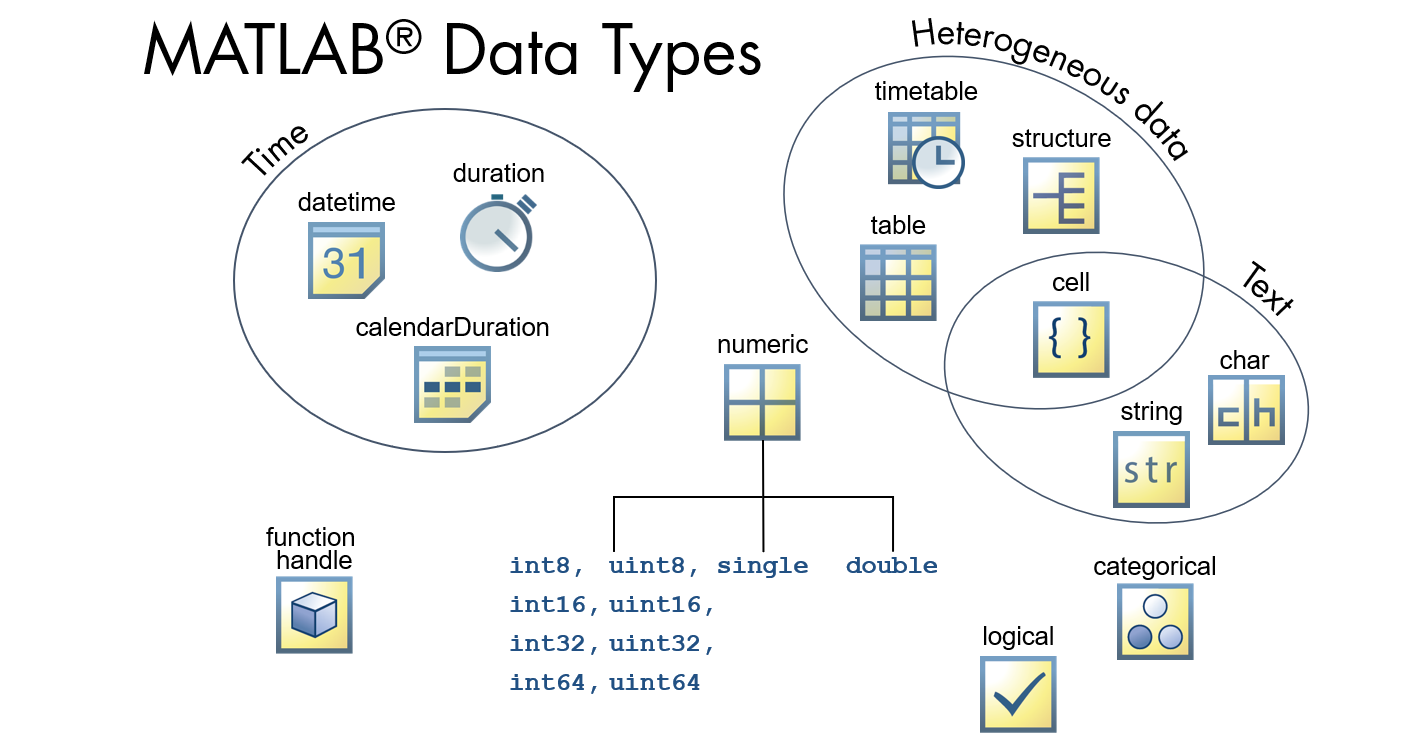

*Tomado de la documentación oficial de MATLAB.*

# Números en MATLAB

Los números en MATLAB incluyen **enteros** con signo y sin signo, y números de **punto flotante** de precisión simple y precisión doble. De forma predeterminada, MATLAB almacena todos los valores numéricos como **punto flotante de precisión doble**.

En otras palabras, tenemos dos tipos de números:

- Enteros (sin decimales)

- Punto flotante (con decimales)

Además de las características que se mencionarán a continuación para cada tipo de número, una de las más importantes es la cantidad de memoria que requiere cada tipo denúmero.

**Figura 2.** Tipo de dato VS. Cantidad de memoria requerida por cada tipo de dato y precisión.

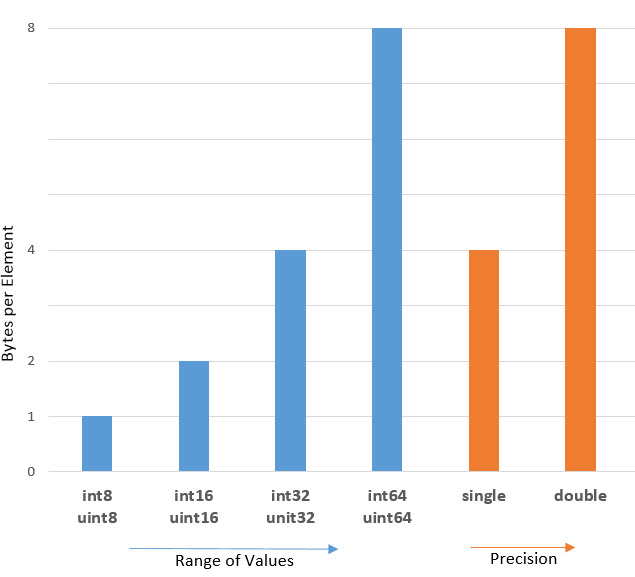

*Tomado y modificado de la documentación oficial de MATLAB.*

## Números de punto flotante (o decimales)

Los números de punto flotante, o de coma flotante, son comúnmente conocidos también como los **números reales dentro de la programación**.

Las funciones para definir números de punto flotante son:

- `double` (por defecto): números de punto flotante de precisión doble de hasta 52 cifras decimales.

- `single`: números de punto flotante de precisión sencilla de hasta 23 cifras decimales.

### Análisis de la precisión de los números de punto flotante

#### Número $\pi$

El número $\pi$ dentro de MATLAB está definido como la constante `pi`.

% Ingrese su código aquí :)

#### Ejemplo

La serie armónica es aquella que suma los inversos multiplicativos de los enteros positivos. Se denota como se muestra a continuación:


$$\sum_{k=1}^{\infty } \frac{1}{k}=1+\frac{1}{2}+\frac{1}{3}+\frac{1}{4}+\frac{1}{5}+\ldots$$


Realizar la suma acumulada de la serie armónica desde $k=1$ hasta $k={10}^7$ con números de precisión doble y números de precisión sencilla. Comparar los resultados mediante una gráfica de línea.

**Nota:** Este ejercicio tiene como objetivo explicar la diferencia, e importancia, de trabajar con números de precisión doble y números de precisión simple. Las funciones, y el código en general, utilizadas aquí se estudiarán a lo largo del curso, por lo que por el momento no son relevantes.

*Ejemplo modificado de Moore, 2007.*

#### Solución

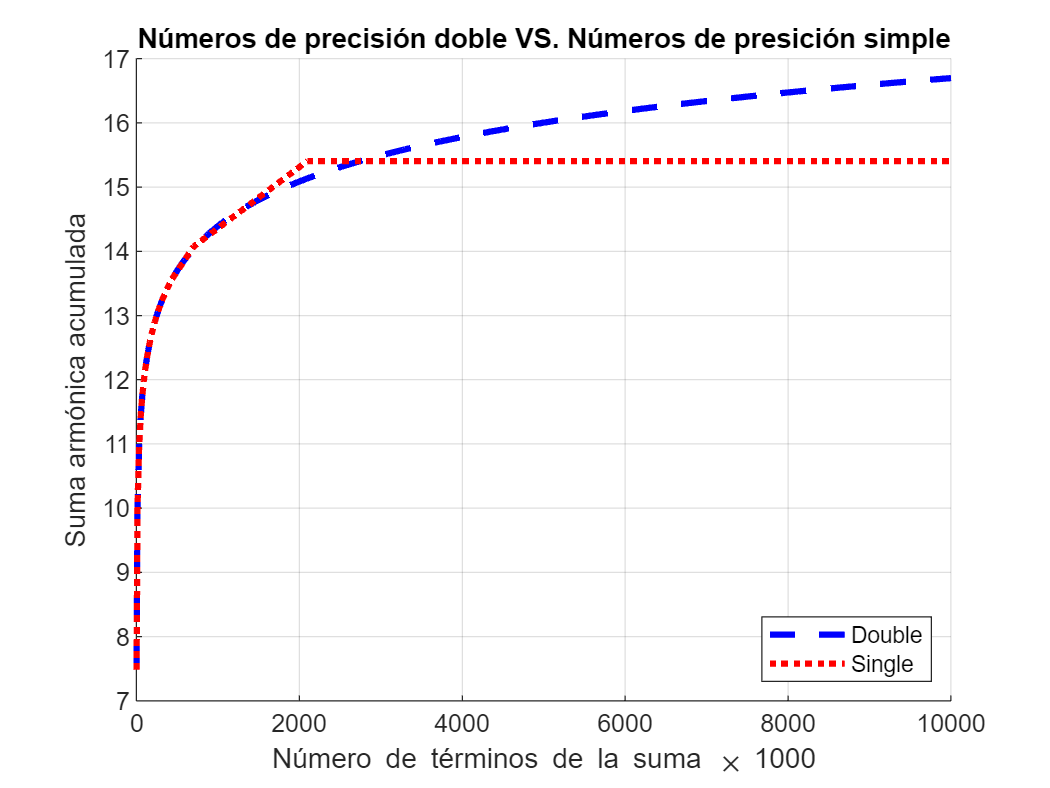

clear

% Límites de la suma.
maxL = 1e7;
idx = 1e3:1e3:maxL;

% Suma armónica acumulada con números de precisión doble.
nDou = 1:maxL;
nDou = 1 ./ nDou;
serieArmDouble = cumsum(nDou);

% Suma armónica acumulada con números de precisión simple.
nSing = single(1:maxL);
nSing = 1 ./ nSing;
serieArmSingle = cumsum(nSing);

% Visualización de las sumas.
figure("Name", "Serie armónica: Double VS. Single")
hold on
plot(serieArmDouble(idx), "b--", "LineWidth", 2.5, "DisplayName", "Double");
plot(serieArmSingle(idx), "r:", "LineWidth", 2.5, "DisplayName", "Single");
hold off

% Mejoramiento de la visualización.
title("Números de precisión doble VS. Números de presición simple")
ylabel("Suma armónica acumulada")
xlabel("Número de términos de la suma \times 1000")
legend("Location", "southeast")
grid

% set(gca, "FontSize", 16, "LineWidth", 1.5)

### Notación científica

La **notación científica**, también denominada notación exponencial, es una forma de escribir los números basada en potencias de 10, lo que resulta especialmente útil para la **representación de valores muy grandes o pequeños**, así como para el cálculo con ellos.

Por ejemplo, la masa del electrón es $0\ldotp 000\;000\;000\;000\;000\;000\;000\;000\;000\;000\;911\;\textrm{kg}=9\ldotp 11\times {10}^{-31} \;\textrm{kg}$. Otro ejemplo, la mayor distancia observable del universo es $740\;000\;000\;000\;000\;000\;000\;000\;000\;\mathrm{m}=7\ldotp 4\times {10}^{26} \;\mathrm{m}$.

Dentro de MATLAB se podrían escribir directamente la expresiones:

Sin embargo, en lugar de ello se puede utilizar la letra `e` y luego indicar la potencia.

% Ingrese su código aquí :)

### Números de punto flotante máximos y mínimos

Matemáticamente hablando, es posible escribir números tan grandes y tan pequeños como queramos. "**El papel aguanta todo**", dijo algún sabio. Sin embargo, como los números dentro de la programación son variables, y por tanto, espacio de memoria dentro de la computadora, y la computadora no tiene espacio infinito, es necesario establecer un límite superior e inferior de los números reales dentro de MATLAB.

Para conocer el número de punto flotante máximo y mínimo se utiliza la función `realmax` y `realmin`, respectivamente; tanto para los números tipo `double` como para los números tipo `single`.

% Ingrese su código aquí :)

#### ¿Qué sucede si se excede el límite máximo o mínimo?

Si se realizan operaciones tal que se excede el límite máximo, entonces el resultado es tan grande que MATLAB ya no lo procesa y devuelve `Inf` (infinito). Este caso se conoce como **desbordamiento**.

% Ingrese su código aquí :)

Por el contrario, si el número es tan pequeño que excede el límite mínimo, entonces MATLAB ya no lo procesa y devuelve `0`. Este caso se conoce como **subdesbordamiento**.

% Ingrese su código aquí :)

Como se puede observar, en ocasiones se puede llegar a los límites o sobrepasarlos y MATLAB sigue procesando información, hasta cuando se excede demasiado y ocurre el desbordamiento o subdesbordamiento.

Sin embargo, **no se recomienda trabajar cerca de las fronteras de los límites de cada tipo de dato**.

## Números enteros

Existen dos tipos de números enteros en MATLAB: enteros con signo y enteros sin signo. La diferencia entre los números enteros con signo y sin signo es el número máximo que pueden guardar.

**Los números enteros sin signo guardan números el doble de grandes que sus contrapartes enteras con signo utilizando el mismo espacio de almacenamiento**.

Las funciones para definir **números enteros con signo** (`signed ``int``eger`) son:

- `int8`

- `int16`

- `int32`

- `int64`

Las funciones para definir **números enteros sin signo** (`u``nsigned ``int``eger`) son:

- `uint8`

- `uint16`

- `uint32`

- `uint64`

% Ingrese su código aquí :)

#### Observación

El número al final de cada función para definir números enteros indica el números de bits que ocupará la variable numérica entera. A mayor número de bits, mayor es el número entero que se puede generar.

### Ejemplo

El archivo `Tema02_Auxiliar_EdificiosMasAltosDelMundo.mat` contiene información sobre los edificios más altos de mundo como la altura (en metros y pies), el número de pisos (subterráneos y superficiales), la ubicación, etc.

Cargar todas las variables del archivo `Tema02_Auxiliar_EdificiosMasAltosDelMundo.mat` y visualizar sus características. ¿Qué variables sería adecuado transformar en números enteros? ¿Por qué?

% Ingrese su código aquí :)

#### ¿Cuándo utilizar números enteros con signo y sin signo?

Si el signo de la variable numérica es irrelevante, como la edad, entonces se debería crear la variable como número entero sin signo. Pero si sí importa el signo entonces se debería utilizar números enteros con signo.

#### Observación

Si se intenta crear un número entero a partir de un número decimal, la función redondeará el número decimal. Si la parte decimal es menor que 5 tomará el entero menor, pero si la parte decimal es mayor que 5 tomará el entero superior.

% Ingrese su código aquí :)

### Números enteros máximos y mínimos

Análogamente a los números de punto flotante, los números enteros también tiene un límite máximo y mínimo, dependiendo si son enteros con signo o enteros sin signo. Las funciones para conocer el límite máximo y mínimo para números enteros son `intmax` e `intmin`, respectivamente.

Los números enteros con signo tienen la mitad del límite superior que sus contrapartes sin signo.

% Ingrese su código aquí :)

Sin embargo, el límite inferior para números enteros con signo y sin signo sí es diferente. Como los números enteros sin signo no tienen eso, un signo, entonces su límite inferior es `0`. En cambio los números enteros con signo sí tienen un límite inferior.

% Ingrese su código aquí :)

#### ¿Qué sucede si se supera el límite superior o límite inferior?

Para los números enteros no ocurre un desbordamiento, únicamente devolverá el número máximo del tipo de entero con el que se esté trabajando.

% Ingrese su código aquí :)

Tampoco ocurre un subdesbordamiento, únicamente devolverá el número mínimo del tipo de entero con el que se esté trabajando.

% Ingrese su código aquí :)

## Números complejos

Los números complejos dentro de MATLAB se definen en forma binomial y la unidad imaginaria tiene dos representaciones: `i` y `j`. Ambas representaciones son iguales a $\sqrt{-1}$, aunque la más usual es `i`.

% Ingrese su código aquí :)

Además, definir la parte imaginaria de un número complejo manualmente **es la única operación donde no se debe indicar explícitamente la multiplicación**.

Aunque MATLAB no generará un error, sí no mostrará un mensaje indicando que no es la manera adecuada de definir un número complejo manualmente.

% Ingrese su código aquí :)

## Función `class`

La función `class` retorna el nombre del **tipo de dato** (conocido también como **clase**) de la variable.

% Ingrese su código aquí :)

## Formatos de visualización

Ahora que ya hemos revisado los números dentro de MALTAB, también es importante conocer las diferentes formas en que se los puede visualizar.

La función `format` permite cambiar la forma de visualizar los números. No los modifica, únicamente cambia su visualización.

A continuación se muestran los estilos disponibles.

**Figura 3.** Estilos de formato numérico.

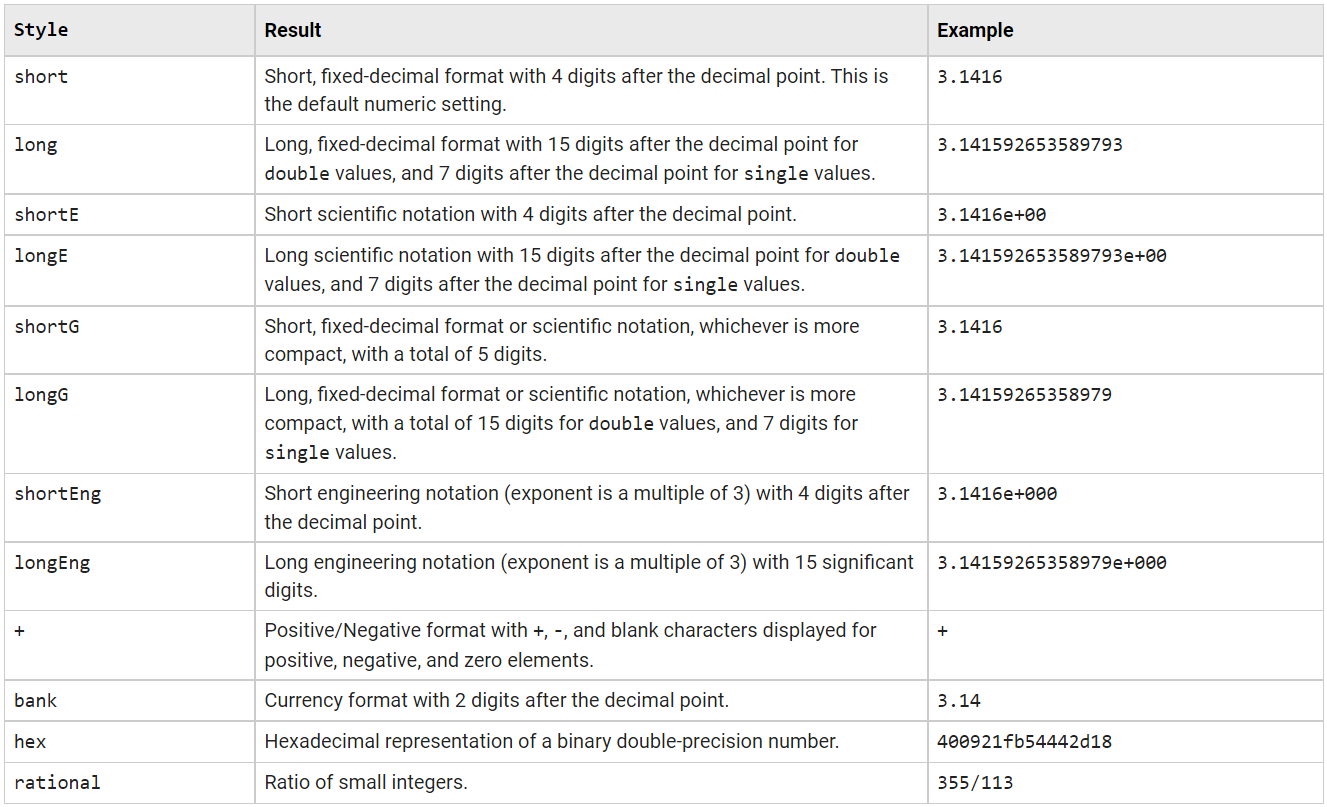

*Tomado de la documentación oficial de MATLAB.*

El estilo predeterminado de MATLAB es `short`, pero podemos cambiarlo por cualquier otro estilo. Una vez se haya cambiado el estilo, éste se matendrá dentro de MATLAB hasta que se indiqué un nuevo estilo o se reestablezca el estilo por defecto (que es el estilo `short`).

% Ingrese su código aquí :)

### Ejemplo

El momento se define como


$$M=F\times \;d$$


donde $M$ es el momento en Newton$\cdot$metro ($\mathrm{N}\cdot \mathrm{m}$), $F$ es la fuerza en Newtons ($\mathrm{N}$) y $d$ es la distancia perpendicular a la fuerza (también conocida como brazo de palanca) en metros ($\mathrm{m}$).

Determinar el momento que generan $14\;052\;\mathrm{N}$ con un brazo de palanca de $142\ldotp 5\;\mathrm{m}$.

% Ingrese su código aquí :)

## Operaciones aritméticas

Las operaciones aritméticas se realizan con los operadores usuales ya conocidos en matemática. Además, se debe indicar explícitamente las operaciones que se desea realizar.

A continuación se detallan las operaciones aritméticas y el porqué la tercera forma es la totalmente correcta dentro de MALTAB.

### Suma

Para sumar dos números se utiliza la función `plus` o la función `+`.

% Ingrese su código aquí :)

### Resta

Para restar dos números se utiliza la función `minus` o la función `-`.

% Ingrese su código aquí :)

### Producto

Para multiplicar dos números se utiliza la función `times` o la función `.*`.

% Ingrese su código aquí :)

#### Observación

 Cuando se trata del **producto entre dos números** no es necesario añadir el punto `.` antes del asterisco `*`.

% Ingrese su código aquí :)

Sin embargo, esto es un caso particular. Más adelante se estudiará este tema con más detalle. De cualquier manera se recomienda **siempre añadir el punto** para evitar posibles errores cuando crece el código.

**Lo anterior mencionado aplica para las operaciones aritméticas de aquí en adelante.**

### Potencia

Para realizar la potencia entre dos números se utiliza la función `power` o la función `.^`.

% Ingrese su código aquí :)

### División

#### División derecha (división usual)

Para dividir dos números (de derecha a izquierda) se utiliza la función `rdivide` o la función `./`.

% Ingrese su código aquí :)

#### División izquierda

Para dividir dos números (de izquierda a derecha) se utiliza la función `ldivide` o la función `.\`.

% Ingrese su código aquí :)

### División entera

En la siguiente imagen se observan las partes de la división. Teniendo esto como base (y para recordar), a continuación se listan las funciones de la divisón entera.

**Figura 4.** Partes de una división.

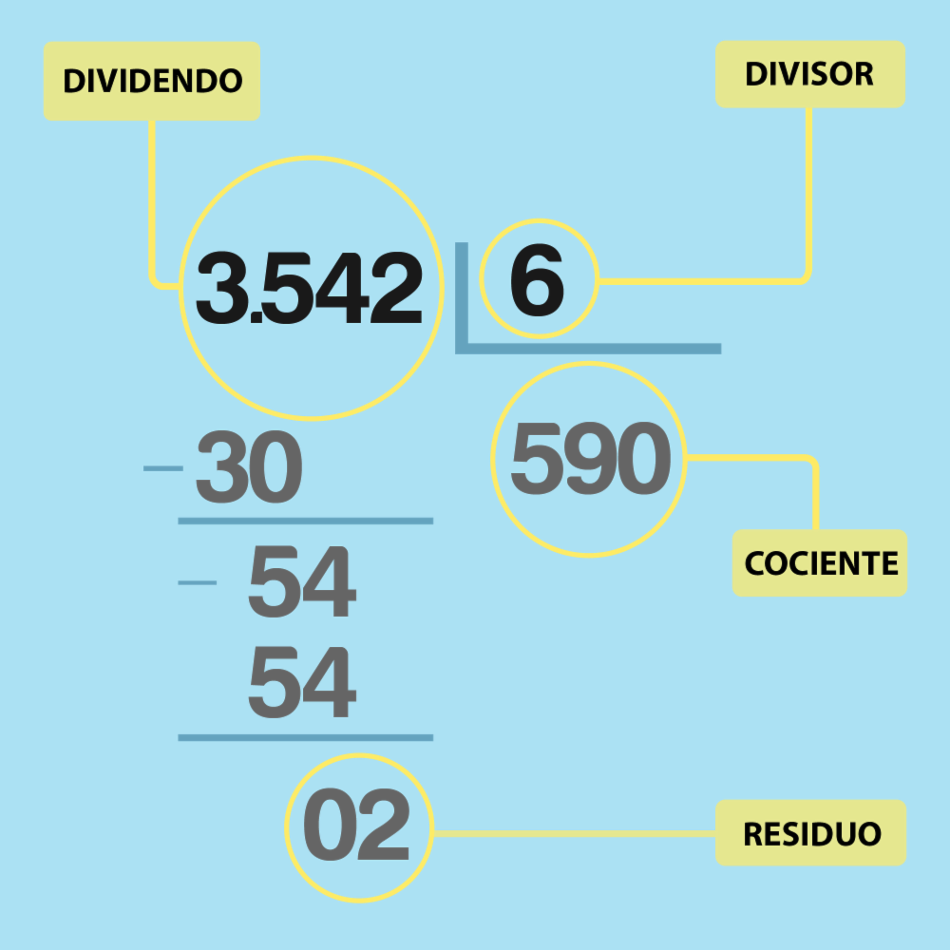

*Tomado de *[*GCF AprendeLibre*](https://aprendizaje.mec.edu.py/dw-recursos/system/content/12c54d4/matematicas/curso/como_dividir/en_que_consiste_una_division/2.do.html)*.*

Para obtener el cociente de la división entre dos números se utiliza la función `idivide`. **Al menos uno de los números con los cuales se realizará la división entera debe ser entero**.

% Ingrese su código aquí :)

#### Observación

Si se desea realizar la división entera entre dos números enteros, **ambos deben ser del mismo tipo**.

% Ingrese su código aquí :)

### Remanente

Para obtener el remanente (o resto) de la división entre dos números se utiliza la función `mod` o la función `rem`.

% Ingrese su código aquí :)

#### ¿Cuál es la diferencia entre la función `rem` y la función `mod`?

La función `mod` produce un resultado que es cero o tiene el mismo signo que el divisor, mientras que la función `rem` produce un resultado que es cero o tiene el mismo signo que el dividendo.

% Ingrese su código aquí :)

Otra diferencia es la convención cuando el divisor es cero. La función `mod` sigue la convención de que `mod(a, 0)` devuelve `a`, mientras que la función `rem` sigue la convención de que `rem(a, 0)` devuelve `NaN`.

% Ingrese su código aquí :)

### Ejemplo

Un sensor ubicado en una avenida muy concurrida registra cuántos automóviles han pasado en cada hora. El sensor realiza los registros durante una semana. Dado que el registro de datos se realiza cada hora, 24 datos por día, y el sensor los ha tomado durante una semana completa, 7 días, entonces el número total de registros es de 168. Sin embargo, el archivo con los registros que nos ha devuelto el sensor tiene una sola columna con los 168 registros.

Sabiendo que el sensor empezó a registrar datos a las 0h00 del día lunes y finalizó el registro a las 0h00 del próximo lunes, ¿habría alguna forma de reorganizar los registros tal que éstos estén distribuidos de mejor manera? Por ejemplo, en filas y columnas en lugar de una sola columna.

Si hubiera una forma de reorganizar la información, ¿se la podría utilizar para reorganizar los datos de otro sensor ubicado en otra avenida, el cual trabajó el mismo perido de tiempo, pero que registró 169 datos?

**Nota:** Utilizar la función `reshape`.

% Ingrese su código aquí :)

## Orden de las operaciones aritméticas

El orden en el cual se llevan a cabo las operaciones aritméticas dentro de MATLAB es el mismo establecido en matemática.

- Paréntesis (desde lo más internos).

- Potencia.

- Multiplicación y división.

- Suma y resta.

En el caso de que hayan varias operaciones del mismo orden, entonces se realizarán las **operaciones de izquierda a derecha**.

% Ingrese su código aquí :)

#### Observación

Cuando se tiene una expresión "larga" como divisor o exponente, por ejemplo, se debe indicar explícitamente.

Por ejemplo, si se tiene la expresión $2^{xy} + 1$, entonces:

% Ingrese su código aquí :)

Es decir, MATLAB toma el primer valor para realizar la respectiva operación cuando no se indica explícitamente la operación deseada.

## Material adicional

- [Tipos de datos numéricos](https://www.mathworks.com/help/matlab/numeric-types.html)

- [Operaciones aritméticas](https://www.mathworks.com/help/matlab/arithmetic.html)

- [División euclídea o entera (Wikipedia)](https://es.wikipedia.org/wiki/Divisi%C3%B3n_eucl%C3%ADdea)

- [Diferencias entre `mod` y `rem`](https://www.mathworks.com/help/matlab/ref/rem.html#bu444r1-2)

- [Precedencia de operadores](https://www.mathworks.com/help/matlab/matlab_prog/operator-precedence.html)

- [Número complejo (Wikipedia)](https://es.wikipedia.org/wiki/N%C3%BAmero_complejo)

- [Números complejos en MATLAB](https://www.mathworks.com/help/matlab/complex-numbers.html)